# 通信原理实验1

姓名：朱天昊

学号：18308267

邮箱：1312622783@qq.com

## 实验目标

1、带通信号的低通等效表示；  

2、随机信号分析。

## 实验条件

MATLAB 2016 and above, Simulink, and Communications System Toolbox .

## Prelab

## Problem 1 概念解释

## 1.a.

基带低通信号，频带带通信号，窄带带通信号，等效低通信号，等效低通信道，解析信号，希尔伯特变换。  

**Answer:**

**基带低通信号：低通信号x(t)，带宽为fm**

**频带带通信号：带通信号x(t)，中心频率为fc，带宽为W**

**窄带带通信号：窄带W<<fc的带通信号**

**等效低通信号：带通信号的等效低通表示**

**等效低通信道：带通信道的等效低通表示**

**解析信号：特殊的带通信号，频谱仅包含正频率部分**

**希尔伯特变换：对输入信号所有频率产生90°的移相。**

## 1.b.

平稳随机过程，窄带随机过程，自相关函数，功率谱密度，随机过程通过线性系统。

**Answer:**

**平稳随机过程：****在固定时间和位置的概率分布与所有时间和位置的概率分布相同的随机过程，即随机过程的统计特性不随时间的推移而变化，因此数学期望和自相关函数这些参数不随时间和位置变化。**

**窄带随机过程：通频带远远小于中心频率的随机过程**

**自相关函数：一个信号于其自身在不同时间点的互相关函数。**

**功率谱密度：每单位频率信号携带的功率（根据维纳—辛钦定理，可由信号自相关函数的傅里叶变换求得）**

**随机过程通过线性系统：当输入平稳，输出也平稳；若输入信号服从高斯分布，输出信号也服从高斯分布。**

## Problem 2

信号$x\left(t\right)=e^{-10\left|t-5\right|} \cos \left(2\pi \times 20t\right),0\le t\le 10$，试求：

1）画出该信号和它的幅度谱。

2）求该信号的解析信号，并画出解析信号幅度谱。

**Answer:**

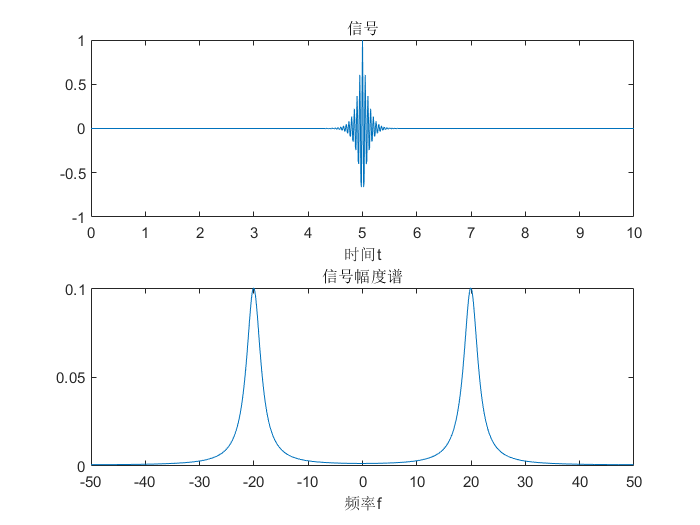

% insert your code here
clear all; close all; clc;
N1=2000;
N2=1000;
x=randn(N2,N1);
for ii=1:N2
    [Rx(ii,:),lags]=xcorr(x(ii,:),500,'coeff');
    Sf(ii,:)=fftshift(abs(fft(Rx(ii,:))));
end
Rx_av=sum(Rx)/N2;
Sf_av=sum(Sf)/N2;
subplot(2,1,1);plot(lags,Rx_av);title('自相关函数')
subplot(2,1,2);plot(lags,Sf_av);title('功率谱密度')
axis([-500 500 0 2])    
ts=0.01;
fs=1/ts;
t=0:ts:10;
df=fs/length(t);
f=-50:df:50-df;
x=exp(-10*abs(t-5)).*cos(2*pi*20*t);
X=fft(x)/fs;

xa=hilbert(x);
Xa=fft(xa)/fs;
subplot(2,1,1);plot(t,x);title('信号');xlabel('时间t')
subplot(2,1,2);plot(f,fftshift(abs(X)));title('信号幅度谱');xlabel('频率f')

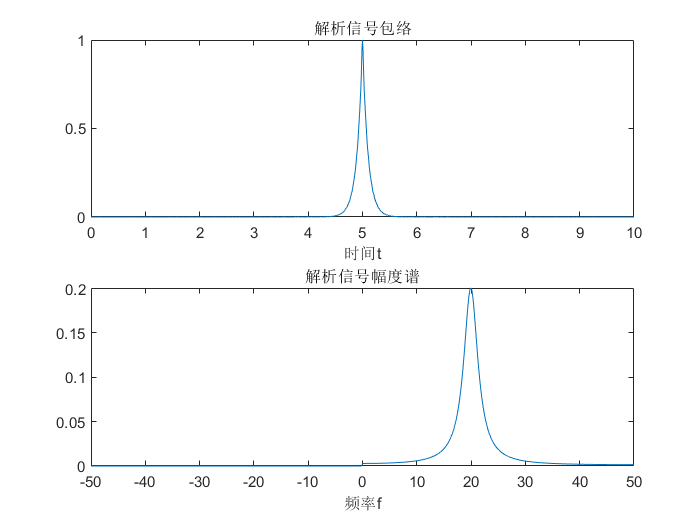


figure
subplot(2,1,1);plot(t,abs(xa));title('解析信号包络');xlabel('时间t')
subplot(2,1,2);plot(f,fftshift(abs(Xa)));title('解析信号幅度谱');xlabel('频率f')

Note：对比观察原信号与其解析信号的功率大小。

## Problem 3

产生1000个N=2000的独立同分布的均值为0，方差为1的高斯分布随机数的离散时间序列，计算该序列的自相关估值和功率谱密度的平均值。

**Answer:**

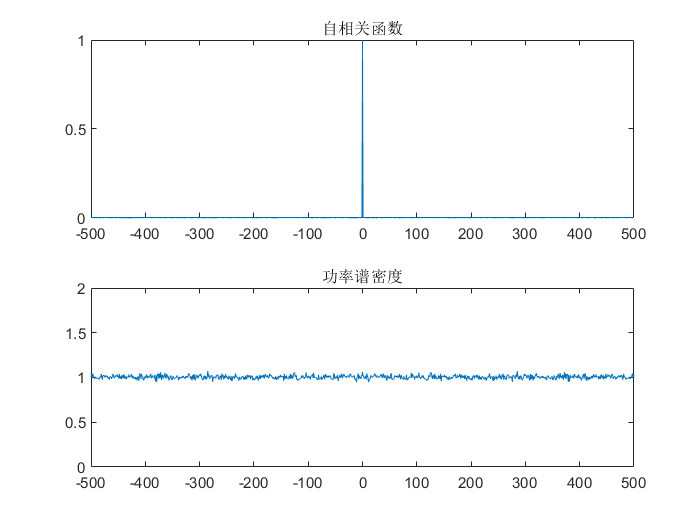

% insert your code here
clear all; close all; clc;
N1=2000;
N2=1000;
x=randn(N2,N1);
for ii=1:N2
    [Rx(ii,:),lags]=xcorr(x(ii,:),500,'coeff');
    Sf(ii,:)=fftshift(abs(fft(Rx(ii,:))));
end
Rx_av=sum(Rx)/N2;
Sf_av=sum(Sf)/N2;
subplot(2,1,1);plot(lags,Rx_av);title('自相关函数')
subplot(2,1,2);plot(lags,Sf_av);title('功率谱密度')
axis([-500 500 0 2])    

Note：“高斯-白”的物理涵义。

## Lab

## Problem 1

信号$a\left(t\right)=\textrm{Re}\left\lbrace a_l \left(t\right)e^{\textrm{j2}\pi f_c t} \right\rbrace ,a\left(t\right)=e^{-10\left|t-5\right|} \cos \left(2\pi \times 20t\right),0\le t\le 10$，试求解下列问题：

1）假设$f_c =20\textrm{Hz}$，求$a\left(t\right)\textrm{的等效低通信号，并画出}$它的幅度谱，同相分量和正交分量；

2）如果$f_c =10\textrm{Hz}$，重复上述操作。

**Answer：**

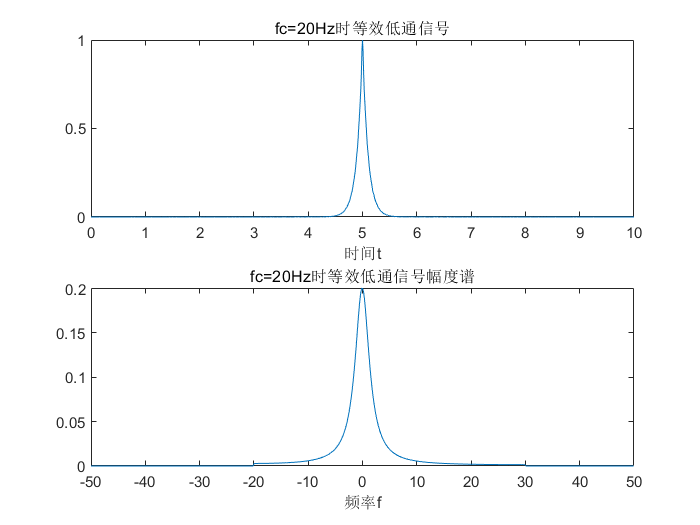

% Insert your code here
clear all; close all; clc;
ts=0.01;
fs=1/ts;
t=0:ts:10;
df=fs/length(t);
f=-50:df:50-df;
a = exp(-10*abs(t-5)).*cos(2*pi*20*t);
A=fft(a)/fs;
aa=hilbert(a);


fc = 20;
al = aa.* exp(-i*2*pi*fc*t);
AL=fft(al)/fs;
al_re = real(al);
Al_re = fft(al_re)/fs;
al_im = imag(al);
Al_im = fft(al_im)/fs;
subplot(2,1,1);plot(t,abs(al));title('fc=20Hz时等效低通信号');xlabel('时间t')                % 等效低通信号
subplot(2,1,2);plot(f,fftshift(abs(AL)));title('fc=20Hz时等效低通信号幅度谱');xlabel('频率f')

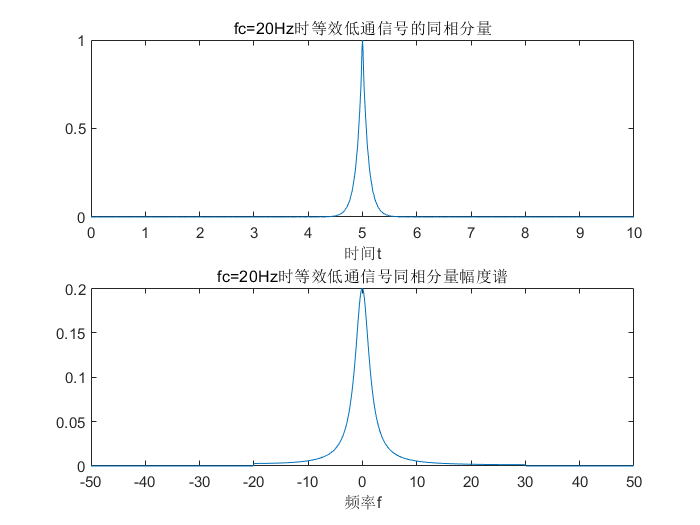

figure;
subplot(2,1,1);plot(t,abs(al_re));title('fc=20Hz时等效低通信号的同相分量');xlabel('时间t')    % 同相分量
subplot(2,1,2);plot(f,fftshift(abs(AL)));title('fc=20Hz时等效低通信号同相分量幅度谱');xlabel('频率f')

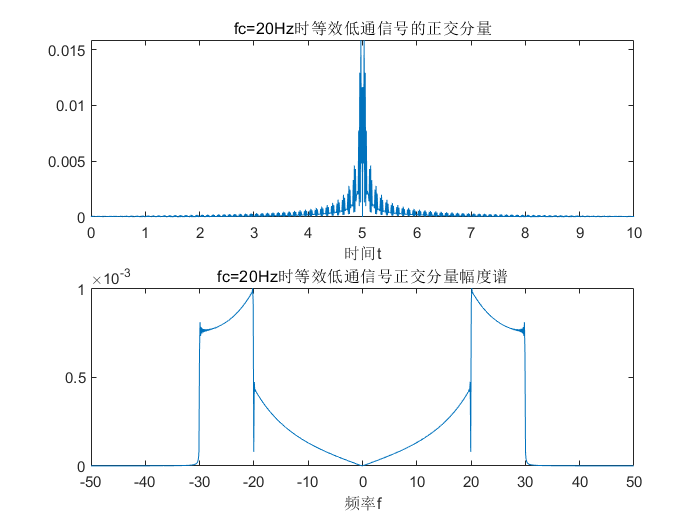

figure;
subplot(2,1,1);plot(t,abs(al_im));title('fc=20Hz时等效低通信号的正交分量');xlabel('时间t')    % 正交分量
subplot(2,1,2);plot(f,fftshift(abs(Al_im)));title('fc=20Hz时等效低通信号正交分量幅度谱');xlabel('频率f')

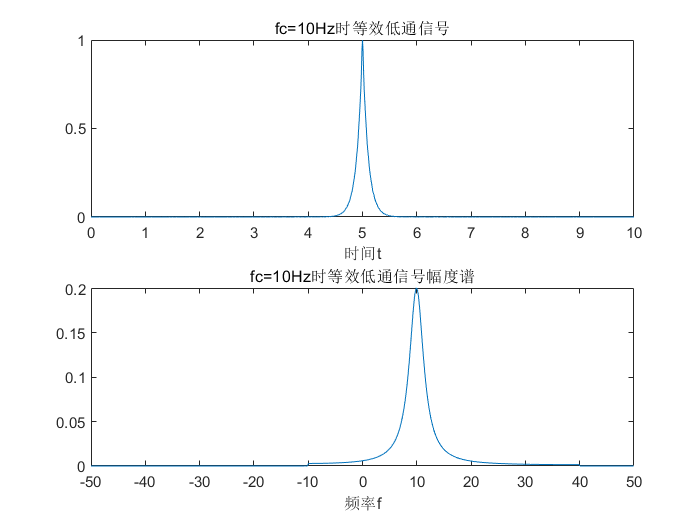


fc = 10;
al = aa.* exp(-i*2*pi*fc*t);
AL=fft(al)/fs;
al_re = real(al);
Al_re = fft(al_re)/fs;
al_im = imag(al);
Al_im = fft(al_im)/fs;
figure;
subplot(2,1,1);plot(t,abs(al));title('fc=10Hz时等效低通信号');xlabel('时间t')                  % 等效低通信号
subplot(2,1,2);plot(f,fftshift(abs(AL)));title('fc=10Hz时等效低通信号幅度谱');xlabel('频率f')

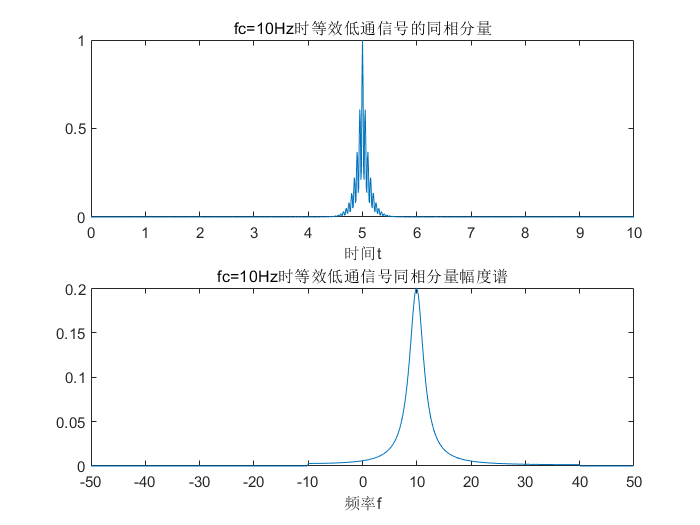

figure;
subplot(2,1,1);plot(t,abs(al_re));title('fc=10Hz时等效低通信号的同相分量');xlabel('时间t')     % 同相分量
subplot(2,1,2);plot(f,fftshift(abs(AL)));title('fc=10Hz时等效低通信号同相分量幅度谱');xlabel('频率f')

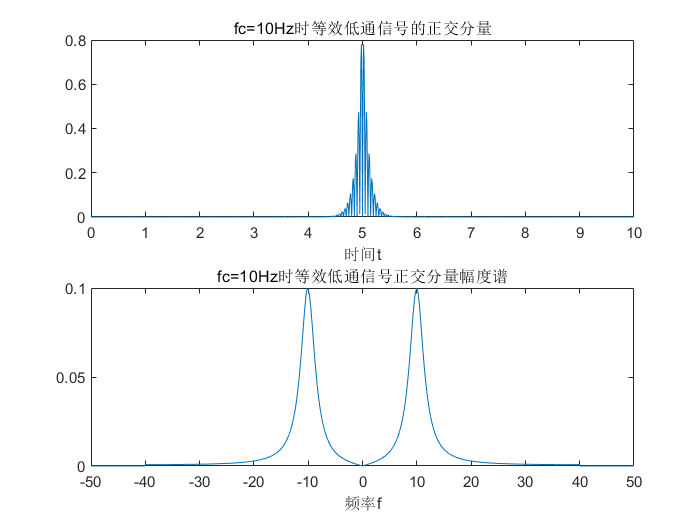

figure;
subplot(2,1,1);plot(t,abs(al_im));title('fc=10Hz时等效低通信号的正交分量');xlabel('时间t')     % 正交分量 
subplot(2,1,2);plot(f,fftshift(abs(Al_im)));title('fc=10Hz时等效低通信号正交分量幅度谱');xlabel('频率f')

## Problem 2

已知一随机过程的自相关函数为$R\left(\tau \right)=\textrm{sinc}\left(2B\tau \right)\cos \left(2\pi f_0 \tau \right)$，其中$B=20,f_0 =100$，试求该随机过程的功率谱密度。

**Answer：**

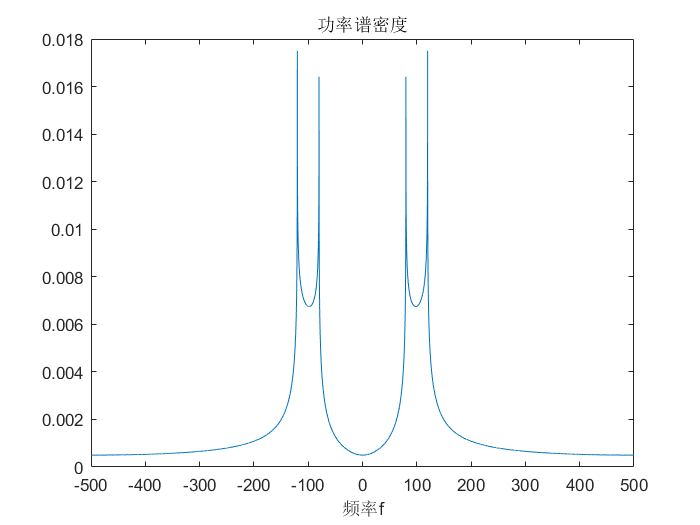

% Insert your code here
clear all; close all; clc;
ts = 0.001;
fs = 1/ts;
tao = 0:ts:10;
df=fs/length(tao);
f=-fs/2:df:fs/2-df;
B = 20; f0 = 100;
Rt = sinc(2*B*tao) .* cos(2*pi*f0*tao);
Pw = fft(Rt)/fs;
plot(f, fftshift(abs(Pw)));title('功率谱密度');xlabel('频率f')

## Problem 3

考虑一个白噪声序列通过一个滤波器产生的序列，滤波器的脉冲响应为$h\left(n\right)=\left\lbrace \begin{array}{cc}
{0\ldotp 6}^n  & ,n\ge 0\\
0 & ,n<0
\end{array}\right.$，输入序列是均值为0，方差为1的高斯分布随机变量的一个独立同分布序列，求输出过程的自相关函数和功率谱密度。

**Answer:**

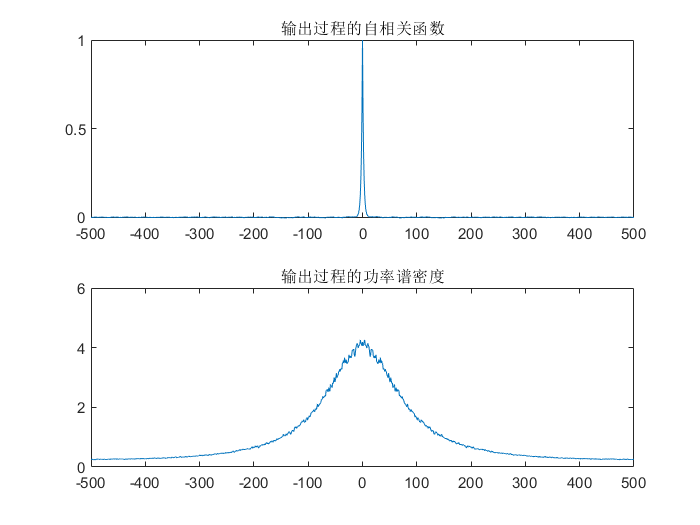

% Insert your code here
clear all; close all; clc;
N2 = 1000;
N1 = 1000;
x = randn(N2,N1);    % 为什么一定要弄成矩阵呢？我用一个一维向量可以表示高斯白噪声序列里吗
for i=1:N2
    y(i,1) = x(i,1);
    for j=2:N1
        y(i,j) = 0.6*y(i,j-1)+x(i,j);    % z变换后可得到它的差分方程，利用差分方程递推y(n)每一个值
    end
    [R(i,:),lags] = xcorr(y(i,:),500,'coeff');
    S(i,:) = fftshift(abs(fft(R(i,:))));
end
R_av = sum(R)/N2;
S_av = sum(S)/N2;
subplot(2,1,1); plot(lags,R_av);title('输出过程的自相关函数');
subplot(2,1,2); plot(lags,S_av);title('输出过程的功率谱密度');
axis([-500 500 0 6]);

## Postlab

*一个带通信号定义如下：*$x\left(t\right)=6\left(\cos \left(20\pi t\right)-3\sin \left(30\pi t\right)\right)\cos \left(400\pi t+\frac{3}{8}\pi t\right)$

*1）画出*$x\left(t\right)$*的谱图；*

*2）画出该信号对应的解析信号的谱图；*

*3）载波频率为200Hz时，求该信号的等效低通信号。*

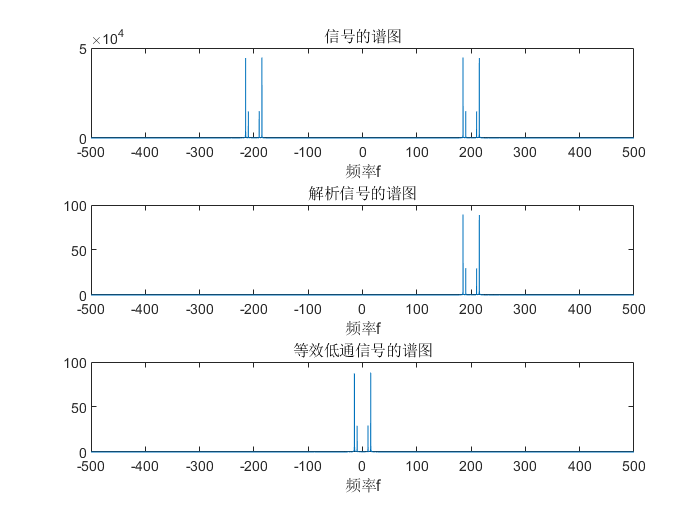

clear all; close all; clc;
ts=0.001;
fs=1/ts;
t=0:ts:10;
df=fs/length(t);
f=-fs/2:df:fs/2-df;
xt = 6*(cos(20*pi.*t)-3*sin(30*pi.*t)).*cos(400*pi.*t+(3/8)*pi.*t);
Xf = fft(xt);

subplot(3,1,1);
plot(f,fftshift(abs(Xf))); title('信号的谱图'); xlabel('频率f')
subplot(3,1,2);
xa = hilbert(xt);
Xa = fft(xa)/fs;
plot(f, fftshift(abs(Xa))); title('解析信号的谱图'); xlabel('频率f')
subplot(3,1,3);
fc = 200;
xl = xa.* exp(-i*2*pi*fc*t);
Xl = fft(xl)/fs;
plot(f,fftshift(abs(Xl))); title('等效低通信号的谱图'); xlabel('频率f')